# GEOS357 Final Project

## [Insert Title Here]

### [Insert Name Here]

## Introduction and Motivation

[Insert text here]

## Importing the Data

[Insert text and code here]

dataDir = "H:\GEOS 357\Final Project\Landsat Files";
cd(dataDir);
Folders = dir("20*");
b = struct();
for j=1:length(Folders);
    cd(Folders(j).name);
    files = dir("*.tif");
    B3 = readgeoraster(files(1).name);
    B6 = readgeoraster(files(2).name);
    B8 = readgeoraster(files(3).name);
    B3_d = double(B3);
    B6_d = double(B6);
    B8_d = im2double(B8);
    b(j).year = Folders(j).name;
    b(j).NDSI = (B3_d-B6_d)./(B3_d+B6_d);
    clear B3* B6*;
    cd ..
end 

## Data Processing

[Insert text and code here]

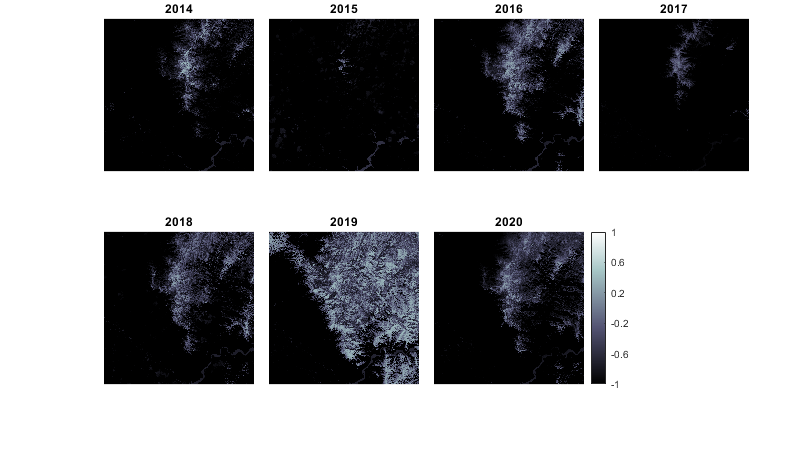

Dates = [2014,2015,2016,2017,2018,2019,2020];
NDSI_Map = figure;
set(NDSI_Map, 'position', [600   568   800   450]);
for j=1:length(Folders);
    subplot(2,4,j);
    snowmap=imshow(b(j).NDSI); colormap("bone");
    subpos = get(gca,'position');
    xlim(gca,[2062.7295401957 3321.90457755102]);
    ylim(gca,[1368.24598241891 2647.04197867342]);
    title(string(Dates(j)));
    if j ==7;
        cbar = colorbar;
        cbar.TickLabels = [-1 -0.6 -0.2 0.2 0.6 1];
    end
    set(gca,'position',[subpos(1),subpos(2),1.2*subpos(3),1.2*subpos(4)]);
    drawnow;
end
saveas(NDSI_Map,"NDSIMap.pdf");

## Data Visualization

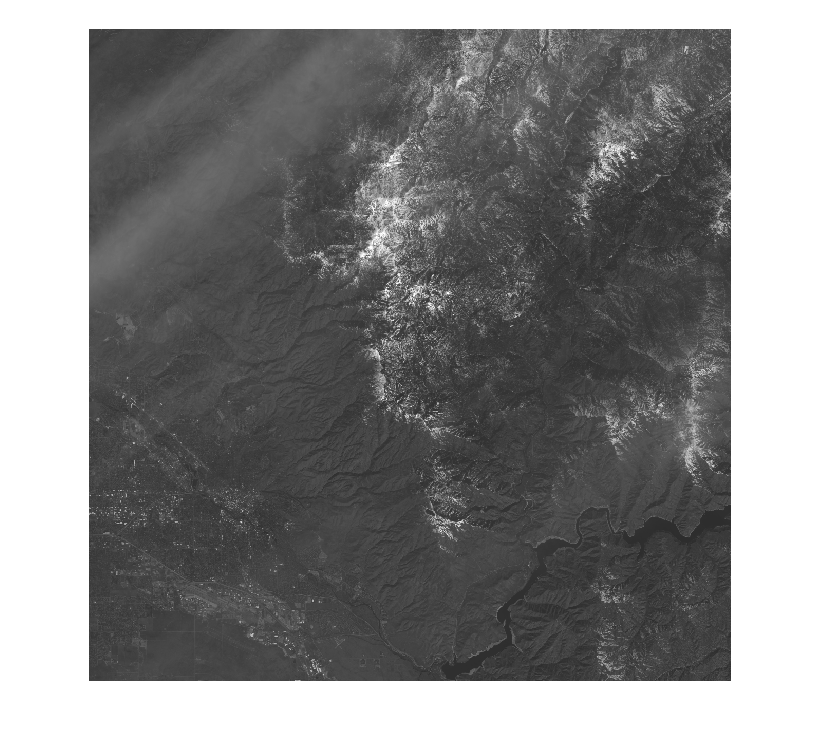

Normal_Map = imadjust(B8_d,[.01,.5],[]);
figure;
imshow(Normal_Map);
xlim(gca,[4190.57481226324 6690.38479411839]);
ylim(gca,[2805.20563898734 5343.97116890072]);

%saveas(Normal_Map,"NormalMap.png");

## Data Analysis

[Insert text and code here]

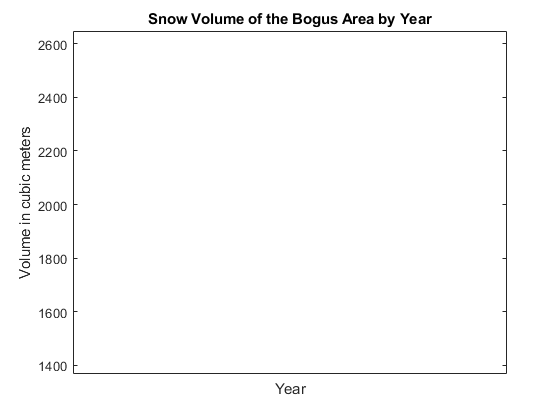

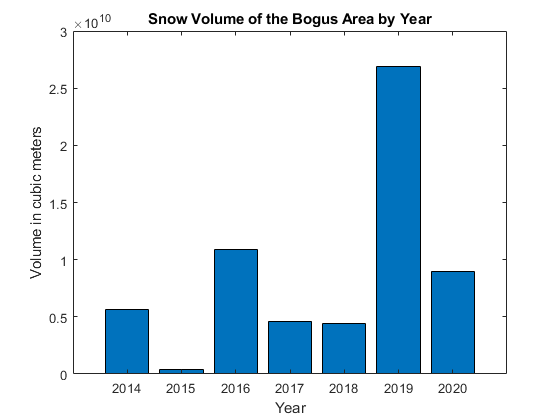

SD = [57.33, 16.71, 68.29, 51.83, 52.13, 86.92, 55.5].*(2.54/100); %These are the average snow depth values recorded at the Bogus Basin Snotel site at the dates the Landsat photos were taken
for j=1:length(Folders);
    map = (b(j).NDSI);
    xlim(gca,[2062.7295401957 3321.90457755102]);
    ylim(gca,[1368.24598241891 2647.04197867342]);
    subpos = get(gca,'position');
    b(j).area = 30.*30.*sum(~isnan(map(map>0.4)));
    volume(j) = b(j).area .* SD(j);
end
Snow_years = [2014:2020];
Snow_Volume = figure;
bar(Snow_years,volume); 
title("Snow Volume of the Bogus Area by Year");
ylabel("Volume in cubic meters");
xlabel("Year");
xlim([2013,2021])
saveas(Snow_Volume,'Volume.png')

## Conclusion

[Insert text here]